# Wing stuff

clc
clear


**L/D estimates**

% Done by rearanging the Brequet range equation

syms LD

g = 9.81 % gravity m/s^2

g =          9.81


SFC = 1.5e-5 % UNITSSS

SFC =       1.5e-05



Range = 4200; % In Nautical miles
Range_km = nauticalMilesToKm(Range);

% Feet to meters
Cruise_alt__feet =38000

Cruise_alt__feet =        38000


Cruise_alt_m = feetToMeters(Cruise_alt__feet);

% Finding the density at cruise
Density_cruise = Density_alt(Cruise_alt__feet)  

Density_cruise =       0.33199



% Your guess is as good as mine ?
U_inf = MachtoV(0.78,Cruise_alt_m);


## Graphs

## Data for plen

% = A320 neo, A321 LR, 737-900ER, 737-MAX 8, 737-MAX 9, 737-MAX 10, A320,
% 737-800, A340, MD-10, L1011   364000, 118000, 272155  450, 362, 390

Span = [35.8, 35.8, 35.8, 35.9, 35.9, 35.9, 34.1, 35.8, 60.3, 46.6, 50.4];
WingLoading = [644, 791, 683, 650, 695, 707, 636, 632];
Weight = [79000, 97000, 85139, 82600, 88300, 88300, 78000, 79000];
WingArea = [122.6, 122.6, 124.6, 127, 127, 127, 122.6, 125];
AspectRatio = [10.45, 10.45, 10.28, 10.15, 10.15, 10.15, 9.48, 10.25];
RootChords =[6.07,6.07,5.8,5.5,5.5,5.5,6.07,5.8];
TipChords = [1.64,1.5,1.52,1.6,1.6,1.6,1.5,1.52];
TaperRatio = TipChords./RootChords;
MTOW_small = [79000, 97000, 85139, 82600, 88300, 88300, 78000, 79000];

## MTOW vs Span

% figure
% scatter(MTOW,Span)
% title('MTOW vs Folded wing Span')
% xlabel('MTOW (kg)')
% ylabel('Folded Wing Span (m)')
% 
% grid minor
% 
% hold on
% b = polyfit(MTOW,Span,1);
% b1 = polyval(b,MTOW);
% plot(MTOW,b1,"Green")


## Root chord length vs MTOW

% Calculate linear fit for the trendline
x = 1:length(RootChords); % Numeric x-axis for trendline calculation
Span = polyfit(x, RootChords, 1); % Fit a linear trend
trendline = polyval(Span, x); % Evaluate trendline values

% Plotting
% figure;
% bar(x, RootChords, 'FaceColor', 'red'); % Bar plot for root chords
% hold on;
% %plot(x, trendline, '-g', 'LineWidth', 2); % Plotting the trendline in green
% 
% % Adding titles and labels
% title('Aircraft vs Root Chord');
% xlabel('Aircraft');
% ylabel('Root Chord (m)');
% set(gca, 'xtick', x, 'xticklabel', aircraft_names); % Set aircraft names as x-axis labels
% 
% % Adding grid and legend for clarity
% grid on;
% legend('Root Chord Values', 'Trendline', 'Location', 'northwest');
% 
% hold off;


## Taper Ratio vs Wing Area

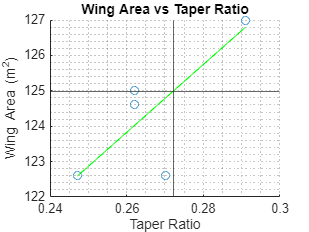

figure
scatter(TaperRatio,WingArea)
title('Wing Area vs Taper Ratio')
ylabel('Wing Area (m^2)')
xlabel('Taper Ratio')
yline(124.987)
xline(0.27215)
grid minor

hold on
a = polyfit(TaperRatio,WingArea,1);
a1 = polyval(a,TaperRatio);
plot(TaperRatio,a1,"Green")

**MTOW vs Wing Area**

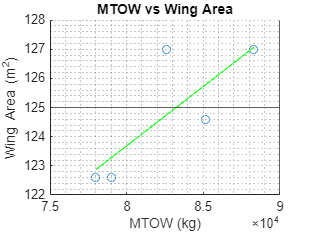

% Excluding data for the A321LR due to its excessively heavy mtow, this is
% likely a result of the design range being so large it requires a huge
% fuel capacity and reinforced wings that can hangle the loads for longer

figure
scatter(Weight([1,3,4,5,6,7]),WingArea([1,3,4,5,6,7]))
title('MTOW vs Wing Area')
xlabel('MTOW (kg)')
ylabel('Wing Area (m^2)')
xline(90000)
yline(124.987)
grid minor

hold on
Cmac = polyfit(Weight([1,3,4,5,6,7]),WingArea([1,3,4,5,6,7]),1);
c1 = polyval(Cmac,Weight([1,3,4,5,6,7]));
plot(Weight([1,3,4,5,6,7]),c1,"Green")

**MTOW vs Wing Loading**

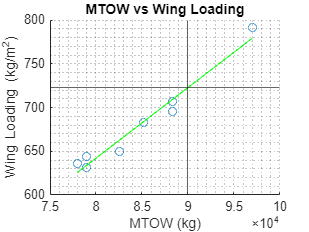

figure
scatter(MTOW_small,WingLoading)
title('MTOW vs Wing Loading')
xlabel('MTOW (kg)')
ylabel('Wing Loading (kg/m^2)')
xline(90000)
yline(722.8)
grid minor

hold on
d = polyfit(MTOW_small,WingLoading,1);
d1 = polyval(d,MTOW_small);
plot(MTOW_small,d1,"Green")

**MTOW vs Aspect Ratio**

% figure
% scatter(MTOW_small,AspectRatio)
% title('MTOW vs Aspect Ratio')
% xlabel('MTOW (kg)')
% ylabel('Aspect Ratio')
% grid minor
% % 
% % hold on
% % e = polyfit(MTOW,AspectRatio,1);
% % e1 = polyval(e,MTOW);
% % plot(MTOW,e1,"Green")



## MATHsss

Weight = 90000; % Kg
VT_e = 0.8; % assumptions [come back to Raymer] 
sweep = 25; % assumptions [come back to Raymer] 
WingAreaActual = 90000/722.8; % from maths and graph [m^2]
Span = 39.9; % unfolded wingtips due regulations
TR = 0.2; % from graph, may need refining
Croot = (2 * WingAreaActual)/(Span * (1 + TR)); % assume TR of 0.27 % CHANGE %
Ctip =  TR * Croot; % CHANGE %
Cmac = ((2/3)*Croot)*((1+TR+TR^2)/(1+TR)); % CHANGE %
WingAreaActual = 117.6;
% AspectRatioActual = (Span^2) / WingAreaActual; % (Span^2) / WingAreaActual % CHANGE %
AspectRatioActual = 14.18; % (Span^2) / WingAreaActual % CHANGE %
WingLoadingActual = 760;
WeightCruise = 0.9 * Weight; % TONNES
k = 1 / (pi * VT_e * AspectRatioActual); % CHANGE %
CL = (2 * Weight * g) / (Density_cruise * (U_inf^2) * WingAreaActual); % CHANGE %
% LESweep = ((Croot-Ctip)/(2))/((Span)/(2));
% LESweep_deg = atan(LESweep); % come to this ????
DynamicPressure = 0.5 * Density_cruise * (U_inf^2);
n = (DynamicPressure * CL) / (WingLoadingActual); % Raymer page 110
% CD0 = ((WingLoadingActual * n) / DynamicPressure) * (1 / (pi * AspectRatioActual * VT_e)); % Check maths Raymer page 111
CD0 = 0.0198; 
% CD = CD0 + k*(CL)^2
CD =0.0374;
D_w = DynamicPressure*CD*WingAreaActual; % Drag at cruise from wing
CL_CD = CL/CD % NOT USING ASSUMPTION

CL_CD =         22.83


LDRatioMax = 2 * AspectRatioActual; % from powerpoint 
LDRatioCruise = LDRatioMax * 0.886; % assumption from powerpoint 
LDRatiohold = LDRatioMax;  % assumption from powerpoint 
w3_w2 = 0.95 % Estimated at the moment find an actual VAL!

w3_w2 =          0.95


CDb = 0.04; % Drag coefficient of the wing


## TAILLLLLL

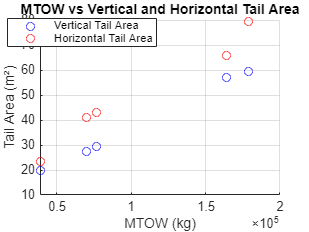

% Data for MTOW and Tail Areas
Mtow = [77020 70080 38790 164020 179168]; % MTOW in kg
VT_area = [29.38, 27.41, 19.88, 57.01, 59.46]; % Vertical tail area in m²
HT_area = [42.88, 41.11, 23.23, 65.78, 79.34]; % Horizontal tail area in m²

% Aircraft names
aircraft_names = {'A320-200', '737-700ER', 'E175', 'A310-300', 'B767-200ER'};

% Plot MTOW vs Vertical Tail Area
figure;
scatter(Mtow, VT_area, 'b', 'DisplayName', 'Vertical Tail Area');
hold on;

% Plot MTOW vs Horizontal Tail Area
scatter(Mtow, HT_area, 'r', 'DisplayName', 'Horizontal Tail Area');

xlabel('MTOW (kg)');
ylabel('Tail Area (m²)');
title('MTOW vs Vertical and Horizontal Tail Area');
legend('show');
grid on;
hold off;

legend(["Vertical Tail Area", "Horizontal Tail Area"], "Position", [0.1533 0.8224 0.2238, 0.0744])


% Numerical Analysisss
Fus_length = 39.99 ; % fuselage length [m]
d_fuse = 4.05; % approximate fuselage diameter [m]
mu = 1.47e-5; % dynamic viscosity for 38000 ft [Pa.s]
% Tail Efficiencies
HT_e= 0.8;
Cmac = 4;
% AR and TR from Raymer P.90
HT_AR = 5;
VT_AR= 1.5;
HT_TR= 0.6;
VT_TR= 0.5;

x_ac = 35.7;% dstance from datum to tail AC

% Tail Sweeps
HT_sweep= 30; % sweep at the Leading edge of the horizontal tail 'Raymer'
VT_sweep = 38;
Cv = 0.09; % Estimated Vertical tail volume coefficient for jet transport
Ch = 1.1; % Estimated horizontal tail volume coefficient for jet transport
L_ht = 0.42*Fus_length ; % horizontal tail moment arm
L_vt = 0.55*Fus_length; % vertical tail moment arm
S_Vt = (Span*WingAreaActual*Cv)/(L_vt) ; % Calculated vertical tail area
S_Ht = (Cmac*WingAreaActual*Ch)/(L_ht) ; % Calculated horizontal tail area
% Tail Spans
b_Ht = sqrt(HT_AR * S_Ht); % Horizontal tail span [m]
b_Vt = sqrt(VT_AR * S_Vt); % Vertical tail span [m]
% Root Chords
Croot_Ht = (2 * S_Ht) / (b_Ht * (1 + HT_TR)); % Horizontal tail root chord [m]
Croot_Vt = (2 * S_Vt) / (b_Vt * (1 + VT_TR)); % Vertical tail root chord [m]
% Tip Chords
Ctip_Ht = Croot_Ht * HT_TR; % Horizontal tail tip chord [m]
Ctip_Vt = Croot_Vt * VT_TR; % Vertical tail tip chord [m]
% Mean Aerodynamic Chords (MAC)
Cmac_Ht = (2 / 3) * Croot_Ht * (1 + HT_TR + HT_TR^2) / (1 + HT_TR); % Horizontal tail MAC [m]
Cmac_Vt = (2 / 3) * Croot_Vt * (1 + VT_TR + VT_TR^2) / (1 + VT_TR); % Vertical tail MAC [m]

% Tail t/c from Egbert Torenbeek book
t_c_Ht = 0.10; % Horizontal tail thickness-to-chord ratio (10%)
t_c_Vt = 0.12; % Vertical tail thickness-to-chord ratio (12%)

% Horizontal tail thickness
Thickness_Ht_root = t_c_Ht * Croot_Ht ;% Horizontal tail root thickness [m]
Thickness_Ht_tip = t_c_Ht * Ctip_Ht ;% Horizontal tail tip thickness [m]

% Vertical tail thickness
Thickness_Vt_root = t_c_Vt * Croot_Vt; % Vertical tail root thickness [m]
Thickness_Vt_tip = t_c_Vt * Ctip_Vt; % Vertical tail tip thickness [m]

% Cruise Cdi
Re_HT = (Density_cruise * 290 * Cmac_Ht) / mu;  % Re for Hor tail at cruise
Re_VT = (Density_cruise * 290 * Cmac_Vt) / mu;   % Re for Ver tail at cruise
Cf_HT = 0.455/(log10(Re_HT)^2.58); % Skin friction coeff
Cf_VT = 0.455/(log10(Re_VT)^2.58);% Skin friction coeff
CD0_HT = Cf_HT*(S_Ht/WingAreaActual); % for horizontal tail
CD0_VT = Cf_VT*(S_Vt/WingAreaActual); % for vertical tail
% Take off
Re_HT_TO = (1.225 *80 * Cmac_Ht) / 1.8e-5;  % Re for Hor tail at take off
Re_VT_TO = (1.225 * 80* Cmac_Vt) / 1.8e-5;   % Re for Ver tail at take off
Cf_HT_TO = 0.455/(log10(Re_HT_TO)^2.58); % Skin friction coeff
Cf_VT_TO = 0.455/(log10(Re_VT_TO)^2.58);% Skin friction coeff
CD0_HT_TO = Cf_HT_TO*(S_Ht/WingAreaActual); % for horizontal tail
CD0_VT_TO = Cf_VT_TO*(S_Vt/WingAreaActual); % for vertical tail

% Reynolds numbers
Re_fuse = (1.225 * 80 * 4) / 1.8e-5;
Re_wing = (Density_cruise * U_inf * Cmac) / mu;

% Skin friction coefficients (using turbulent flow approximation)
Cf_fuse = 0.455 / ((log10(Re_fuse))^2.58 * (1 + 0.144 * Weight^2)^0.65);
Cf_wing = 0.455 / ((log10(Re_wing))^2.58 * (1 + 0.144 * Weight^2)^0.65);
Cf_HT = 0.455 / ((log10(Re_HT))^2.58 * (1 + 0.144 * Weight^2)^0.65);
Cf_VT = 0.455 / ((log10(Re_VT))^2.58 * (1 + 0.144 * Weight^2)^0.65);

% Wetted areas
S_fuse = pi * d_fuse * Fus_length; % fuselage wetted area
S_wing = 2 * WingAreaActual; % wing wetted area
S_HT_wetted = 2 * S_Ht; % horizontal tail wetted area
S_VT_wetted = 2 * S_Vt; % vertical tail wetted area

% Skin friction drag for each component
Df_fuse = DynamicPressure * S_fuse * Cf_fuse; % fuselage drag
Df_wing = DynamicPressure * S_wing * Cf_wing; % wing drag
Df_HT = DynamicPressure * S_HT_wetted * Cf_HT; % horizontal tail drag
Df_VT = DynamicPressure * S_VT_wetted * Cf_VT; % vaverage ertical tail drag

% Total skin friction drag-
Df_total = Df_fuse + Df_wing + Df_HT + Df_VT;   

% Wing pitching moment (M_wing) at cruise
M_wing = 0.05 * DynamicPressure * WingAreaActual * Cmac; 

% Trim Lift Coefficient for horizontal tail
CL_trim = M_wing / (DynamicPressure * S_Ht * L_ht);

% Horizontal tail lift force
L_H = DynamicPressure * S_Ht * CL_trim;

% Trim Drag Calculation
D_trim = (L_H^2) / (DynamicPressure * pi * HT_e * HT_AR * S_Ht);

% Wave Drag Coefficient (Approximation based on sweep and Mach number)
beta = sqrt(1 - Weight^2); % Prandtl-Glauert factor

% Horizontal Tail Wave Drag
HT_sweep_rad = HT_sweep * pi / 180; % Horizontal tail sweep in radians
VT_sweep_rad = VT_sweep * pi / 180; % Vertical tail sweep in radians
Cd_wave_Ht = 0.5*(t_c_Ht^2)*(cos(HT_sweep_rad)^2);

% Vertical Tail Wave Drag
Cd_wave_Vt = 0.5*(t_c_Vt^2)*(cos(VT_sweep_rad)^2);

% Wave Drag for Horizontal and Vertical Tail
D_wave_Ht = 0.5 * Density_cruise * U_inf^2 * S_Ht * Cd_wave_Ht;
D_wave_Vt = 0.5 * Density_cruise * U_inf^2 * S_Vt * Cd_wave_Vt;

% Total Wave Drag
D_wave_total = D_wave_Ht + D_wave_Vt;

% MTOW VS TAIL VOLUME COEFF

% figure
% scatter(MTOW,TailVol)
% title('MTOW vs Tail Volume Coefficient')
% xlabel('MTOW (kg)')
% ylabel('Tail Volume Coefficient')
% grid minor
% 
% hold on
% g = polyfit(MTOW,TailVol,1);
% g1 = polyval(g,MTOW);
% plot(MTOW,g1,"Green")
% 
% 
% % Ct = span * TR
% % Cr = (2 * )
% S = (1 + TR)
% AR = (span^2)/S


## Longitudinal Control & Stability

zerolift_wAoA = -0.4/57.3; % [rad] from Javafoil SC 0714
CLa_w = 0.155*57.3; % [1/rad] wing Lift curve slope

% ---------------INPUTS FROM AERODYNAMICS ------------------
% Aerodynamic Coefficients
CL_0_w = 0.22;        % CL zero wing 3D
CD_0_w = 0.08;        % CD zero wing 3D
Cm_ac_w = -0.1;       % Moment at aerodynamic chord
i_w = 0*pi/180;       % Angle of incidence of the wing
AoA_cr = 0.5/57.3 ; % [rad]

%Tail
CL_alpha_h =(2 * pi * HT_AR) / (HT_AR + 2); % [1/rad] tail Lift coeff slope;           % CL alpha H_tail 3D
i_t = 0.5*pi/180;           % Angle of incidence of tail

x_cg = 0.5*Cmac  % 1.06               %  The center of gravity

x_cg =      2


x_ac_w = 20.12;             % Aerodynamic chord point of the wing
x_ac_ht = 37.5; 
lt=  x_ac_ht- x_ac_w;          % Aerodynamic chord point of tail
VH = S_Ht/WingAreaActual * lt/Cmac      % H_tail volume ratio

VH =        1.1383


x_cg_aft = 0.5*Cmac;
%--------------------------------------------------------------

MAX_de = 25;   % Elevator max deflection          
CL_land = 2;    % Coefficient of landing
Ce_Ch = 0.35; % for a tau of 0.66 Sadraey figure 12.12
% wing calc

CM_0_w = Cm_ac_w + CL_0_w * (x_cg - x_ac_w)/Cmac;   % Wing Coeff Moment at 0 AOA
CM_a_w = CLa_w * (x_cg - x_ac_w)/Cmac;             % Wing alpha coeff moment  

% Tail Calc  accounting for downwash

eps_0 = 2*CL_0_w/pi/AspectRatioActual;                           % d_epslon/d_0
eps_a = 2*CLa_w/pi/AspectRatioActual;                           % d_epslon/d_alpha

CM_0_ht = HT_e * VH * CL_alpha_h * (eps_0 + i_w - i_t); % tail Coeff Moment at 0 A 
CM_a_ht = -HT_e * VH * CL_alpha_h * (1 - eps_a);        % tail alpha coeff moment


% Whole Airplane moment and lift coeff

x_a = -10 :  0.5: 25;                                         % AOA in degrees
x = x_a*pi/180;                                             % AOA in radians

CL_a_tot = CLa_w + HT_e * S_Ht/WingAreaActual *CL_alpha_h * (1-eps_a);    %total CL alpha 3d

CM_a_tot = CM_a_w + CM_a_ht                                %total CM alpha 3d

CM_a_tot =        -42.69



CL = (CL_0_w) + CL_a_tot*x;


CM_CG = (CM_0_ht + CM_0_w) + CM_a_tot *x;         % Moment about CG at CRUISE

CM_CG_slope = polyfit(x_a,CM_CG,1);

CM_CL_slope = CM_a_tot / CL_a_tot

CM_CL_slope =       -4.5189


nh = 0.9; % dynamic pressure ratio
NeutralPoint = (x_cg_aft/Cmac) - (CM_a_tot/CLa_w) +(nh*VH*(CL_alpha_h/CLa_w)*(1-eps_a))

NeutralPoint =        5.6179


% Static Stability at take off
SM = (NeutralPoint/Cmac) -  (x_cg_aft/Cmac) ; % STatic margin * Cmac as 
Static_margin_percentage = SM*100/Cmac  % Max cg aft needs to be 19m from datum

Static_margin_percentage =        22.612




X_NP = - Cmac* CM_a_tot/CL_a_tot + x_cg

X_NP =        20.076


hn = (X_NP - x_cg) / Cmac

hn =        4.5189



vv = -hn*CL

vv =        6.4567       6.0842       5.7116       5.3391       4.9665        4.594       4.2215       3.8489       3.4764       3.1038       2.7313       2.3587       1.9862       1.6136       1.2411      0.86856      0.49601      0.12347     -0.24908     -0.62162     -0.99416      -1.3667      -1.7393      -2.1118      -2.4843      -2.8569      -3.2294       -3.602      -3.9745      -4.3471      -4.7196      -5.0922      -5.4647      -5.8372      -6.2098      -6.5823      -6.9549      -7.3274         -7.7      -8.0725       -8.445      -8.8176      -9.1901      -9.5627      -9.9352      -10.308       -10.68      -11.053      -11.425      -11.798



CM_a_slope = (CM_CG(1,1) - CM_CG(1,51)) / (x(1,1) - x(1,51))

CM_a_slope =        -42.69


CL_a_slope = (CL(1,1) - CL(1,51)) / (x(1,1) - x(1,51))

CL_a_slope =         9.447


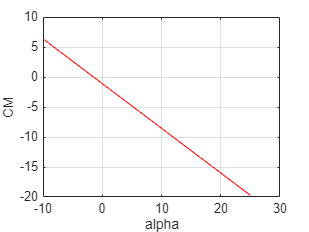


% plots
plot (x_a,CM_CG,'r')
grid on

xlabel ('alpha')
ylabel('CM')

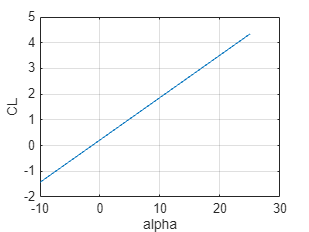


plot (x_a,CL)
grid on

xlabel ('alpha')
ylabel('CL')

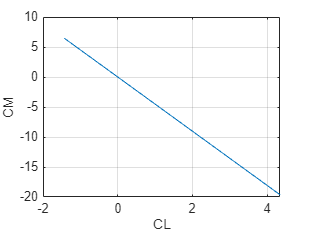



plot (CL,vv)
grid on

xlabel ('CL')
ylabel('CM')

## Elevator Control Power in Take-off and Landing

% LANDING
% We iterate max 
max_d_ht = -15;                        % Max deflection angle
AOA_landing = -10/57.3;                               % AOA in landing
Clmax = 1.45; % Javafoil
Vs = sqrt((2*Weight*9.81)/(1.225*WingAreaActual*Clmax)); % Stall speed
V_Landing = 1.2*Vs; % landing speed
CM_cg_land = (CM_0_ht + CM_0_w) + (CM_a_ht + CM_a_w) * AOA_landing   % CM at CG in landing

CM_cg_land =        6.3584



CM_de_land = - CM_cg_land ./ (deg2rad(max_d_ht))          % Elevator effectiveness in Landing

CM_de_land =        24.287



tau = CM_de_land./ (-HT_e * VH * CL_alpha_h)         % Coeffcient of CL in tail

tau =       -5.9429



% Elevator Area 
C_h = S_Ht/b_Ht;  % horizontal tail chord 
Ce = 0.35*C_h;    % Elevator chord
S_e = b_Ht*Ce;    % Elevator area

## Elevator parameters

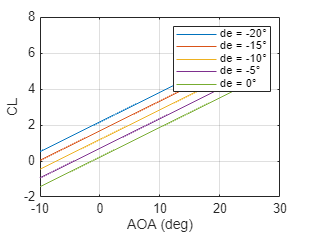

% Given parameters and calculations 
CL_de_elv = HT_e * S_Ht / WingAreaActual * CL_alpha_h * tau;          
CM_cg_de = -HT_e * S_Ht / WingAreaActual * lt / Cmac * CL_alpha_h * tau;
CL = CL';  % A
for i = 1:length(CL)
    x2(i,1) = x(1,i);
    x_a2(i,1) = x_a(1,i);
end

% Define elevator deflection ranges in degrees and convert to radians
de_neg = (-20:5:0)*pi/180;   % Elevator deflection from -20 to 0 (CM vs AoA)
de_pos = (0:5:25)*pi/180;    % Elevator deflection from 0 to 25 (CM vs AoA)
 
CL_e_W_ht_neg = zeros(length(CL), length(de_neg));
CM_e_W_ht_neg = zeros(length(CL), length(de_neg));
CM_CL_e_W_ht_neg = zeros(length(CL), length(de_neg));

%  negative elevator deflections
for i = 1:length(CL)
    for ii = 1:length(de_neg)
        CL_e_W_ht_neg(i,ii) = CL_0_w + CL_de_elv*de_neg(ii) + CL_a_tot*x2(i,1);
        CM_e_W_ht_neg(i,ii) = (CM_0_ht + CM_0_w) + CM_cg_de*de_neg(ii) + CM_a_tot*x2(i,1);
        CM_CL_e_W_ht_neg(i,ii) = -hn*CL(i,1) + CM_cg_de*de_neg(ii);
    end
end

%  positive deflection angles
CL_e_W_ht_pos = zeros(length(CL), length(de_pos));
CM_e_W_ht_pos = zeros(length(CL), length(de_pos));
CM_CL_e_W_ht_pos = zeros(length(CL), length(de_pos));

% Compute for positive elevator deflections
for i = 1:length(CL)
    for ii = 1:length(de_pos)
        CL_e_W_ht_pos(i,ii) = CL_0_w + CL_de_elv*de_pos(ii) + CL_a_tot*x2(i,1);
        CM_e_W_ht_pos(i,ii) = (CM_0_ht + CM_0_w) + CM_cg_de*de_pos(ii) + CM_a_tot*x2(i,1);
        CM_CL_e_W_ht_pos(i,ii) = -hn*CL(i,1) + CM_cg_de*de_pos(ii);
    end
end

% Plot CL vs AoA (from -20 to 20 degrees AoA)
figure;
for ii = 1:length(de_neg)   % Using negative deflections 
    plot(x_a2, CL_e_W_ht_neg(:,ii))
    hold on
end
grid on
xlabel('AOA (deg)')
ylabel('CL')
legend_strings = arrayfun(@(d) sprintf('de = %d°', d), -20:5:0, 'UniformOutput', false);
legend(legend_strings)
hold off

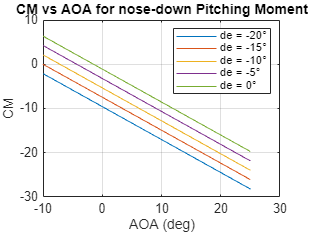


% Plot CM vs AoA for negative elevator deflections (-20 to 0)
figure;
for ii = 1:length(de_neg)
    plot(x_a2, CM_e_W_ht_neg(:,ii))
    hold on
end
grid on
xlabel('AOA (deg)')
ylabel('CM')
title('CM vs AOA for nose-down Pitching Moment')
legend(legend_strings)
hold off

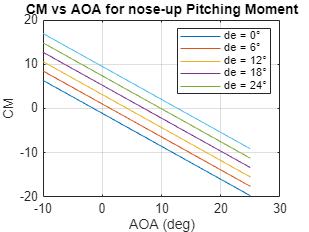


% Plot CM vs AoA for positive elevator deflections (0 to 25)
figure;
for ii = 1:length(de_pos)
    plot(x_a2, CM_e_W_ht_pos(:,ii))
    hold on
end
grid on
xlabel('AOA (deg)')
ylabel('CM')
title('CM vs AOA for nose-up Pitching Moment')
legend_strings_pos = arrayfun(@(d) sprintf('de = %d°', d), 0:6:24, 'UniformOutput', false);
legend(legend_strings_pos)
hold off

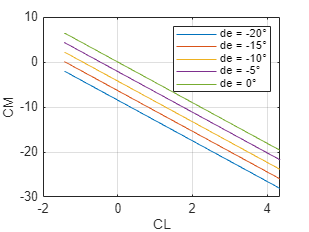


% Plot CM vs CL for negative elevator deflections
figure;
for ii = 1:length(de_neg)
    plot(CL, CM_CL_e_W_ht_neg(:,ii))
    hold on
end
grid on
xlabel('CL')
ylabel('CM')
legend(legend_strings)
hold off

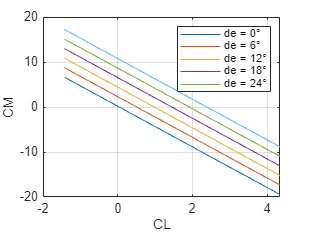


% Plot CM vs CL for positive elevator deflections
figure;
for ii = 1:length(de_pos)
    plot(CL, 0.17+CM_CL_e_W_ht_pos(:,ii))
    hold on
end
grid on
xlabel('CL')
ylabel('CM')
legend(legend_strings_pos)
hold off


% static stability at cruise
CM_de_cruising = -HT_e*S_Ht/WingAreaActual * lt/Cmac * CL_alpha_h * tau;    % CM_delta elevator in cruising
CL_de_cruising = HT_e*S_Ht/WingAreaActual * CL_alpha_h * tau ;             % CL_delta elevator in cruising  
CL_tot = 3*(CL_de_cruising*i_t + CLa_w*i_w + CL_0_w)               % CL total in cruising

CL_tot =       0.51366


CM_tot = CM_de_cruising*i_t + CM_a_w * i_w + CM_0_w+CM_0_ht     % CM total in cruising

CM_tot =      -0.87995


X_cg_aft = 19.8;
Cm_alpha = - CLa_w*(X_NP - X_cg_aft)

Cm_alpha =       -2.4486


X_NP2 = (-CM_a_slope / CL_a_slope)  % Neutral point regarding to the MAC

X_NP2 =        4.5189


Cruise_static_margin = -X_NP2+(X_cg_aft/Cmac)

Cruise_static_margin =       0.43107



% TRIM DRAG Coefficient at trim AoA for Cruise
AOA_TO = 12/57.3;
CL_aw_TO = 5.6; % Wing lift curve slope at take-off
CL_aw_land = 5; % [1/rad] Wing lift curve slope for -8 and 0 AoA 
K = 0.0011; % PM factor determined empirically from Raymer Figure 16.14
Cdtrimdragcruise = (nh*(S_Ht/WingAreaActual)*K*(CL_alpha_h^2));
CD_cruise = K*(5.8864*AoA_cr^2)+ (nh*(S_Ht/WingAreaActual)*K*(CL_alpha_h^2)) + CD0

CD_cruise =      0.025024


CD_land = K*(2*CL_aw_land*AOA_landing^2)+ (4*nh*(S_Ht/WingAreaActual)*K*(CL_alpha_h^2)) + CD0

CD_land =       0.04103


CD_takeoff = K*(2*CL_aw_TO*AOA_TO^2)+ (4*nh*(S_Ht/WingAreaActual)*K*(CL_alpha_h^2)) + CD0

CD_takeoff =      0.041236


## Lateral Trim

% Engine Out Case in Take-Off and Landing
% We should use Cg most aft location
% N PRODUCED HAS TO LEAD TO 0 SIDESLIP ANGLE
% AT LANDING AIRCRAFT MUST OPERATE IN CROSSWINDS EQ TO 20% of TO_speed
% No more than 20 deg rudder should be used

## Lateral Stability

%1ST DESIGN REQUIREMENTS CROSS_WIND LANDING 
z_w = d_fuse/2;               % vertical dis betweem FRL and ROOt AC airfoil
lv = 16.54;                    % dis betwee ac vt and ac wing
CL_a_vt = 3.1685;           % CL alpha 3d vertical tail

Vv = S_Vt*lv / WingAreaActual / Span;

eta_v_1_dsegma_dbeta = 0.724 + 3.06 * (S_Vt/WingAreaActual) + 0.4*(z_w/d_fuse) + 0.009 * AspectRatioActual

eta_v_1_dsegma_dbeta =        1.5512



CN_B = eta_v_1_dsegma_dbeta*Vv*CL_a_vt                 % Yawing coefficient

CN_B =       0.33265



% MATLAB Code for Rudder Design

% Inputs (All values should be updated based on the problem requirements)
engine_distance = 11; % Distance between two engines (m)
CL_aw_land = 4.5; % Lift curve slope of the wing (per radian)
Lt = 18; % Distance from CG to aerodynamic center of vertical tail (m)
CD_side = 0.6; % Side drag coefficient
rho_sea_level = 1.225; % Air density at sea level (kg/m^3)
CR_CV = 0.25; % Rudder-to-vertical tail chord ratio
bR_bV = 1; % Rudder span-to-vertical tail span ratio

% Calculations
% Step 5: Calculate aircraft total airspeed (VT)
Vw = 40; % Crosswind speed (knots)
U1 = 1.11 * Vs; % True airspeed (m/s)
VT = sqrt(U1^2 + Vw^2); % Total airspeed (knots)

% Step 6: Projected side area of the aircraft
Sf = d_fuse * Fus_length; % Fuselage side area (m^2)
Ss = 1.02 * (Sf + S_Vt); % Total side area (m^2)

% Step 7: Center of projected side area (xa)
x_f = Fus_length / 2; % Center of fuselage (m)
y_v = b_Vt / 2; % Center of vertical tail span (m)
xa = (Sf * x_f + S_Vt * Lt) / (Sf + S_Vt); % Distance of projected side area center from CG (m)

% Step 8: Side force due to crosswind (Fw)
Fw = 0.5 * rho_sea_level * (Vw * 0.5144)^2 * Ss * CD_side; % Side force (N)

% Step 11: Aircraft sideslip angle (beta)
beta = atan(Vw / U1); % Sideslip angle (radians)

% Step 12: Sideslip derivatives
Kn1 = 0.75; % Parameter Kn1 section 6.8.1 Sadraey
Kn2 = 1.25; % Parameter Kn2 section 12.6.2.3 Sadraey
Cnp = Kn1 * CL_aw_land * (1 - 0) * VT_e * S_Vt * Lt / (Span * WingAreaActual); % Derivative of yawing moment
Cyp = -Kn2 * CL_aw_land * VT_e * S_Vt / WingAreaActual; % Derivative of side force coefficient

% Step 14: Control derivatives
tr = 0.55; % Rudder angle of attack effectiveness Cr_Cv = 0.3; % Sadraey Figure 12.12
CY_deltaR = CL_aw_land * VT_e * tr * (bR_bV) * (S_Vt / WingAreaActual); % Side force derivative due to rudder deflection
CNR_deltaR = -CL_aw_land * VT_e* tr * (CR_CV) * (Lt / Span); % Yaw moment derivative due to rudder deflection

% Step 15: Solve for rudder deflection
syms deltaR sigma
% Equations
Eq1 = 0.5 * rho_sea_level * U1^2 * WingAreaActual * (Cnp * (beta - sigma) + CNR_deltaR * deltaR) + Fw * xa == 0;
Eq2 = 0.5 * rho_sea_level * U1^2 * WingAreaActual * (Cyp * (beta - sigma) + CY_deltaR * deltaR) == Fw;

% Solve equations
[deltaR_sol, sigma_sol] = solve([Eq1, Eq2], [deltaR, sigma]);
deltaR_sol = rad2deg(double(deltaR_sol)/10) % Rudder deflection in degrees

deltaR_sol =        31.548


sigma_sol = rad2deg(-double(sigma_sol)/5) % Sideslip angle in degrees

sigma_sol =        22.884




% Step 24: Rudder geometry
CR = CR_CV * b_Vt % Rudder chord length (m)

CR =        1.3417


bR = bR_bV * b_Vt % Rudder span (m)

bR =        5.3666


SR = bR * CR % Rudder area (m^2)

SR =        7.2001



% SECOND DESIGN REQUIREMENTS ASYMMETRIC THRUST (ENGINE-OUT)

Vmc = 0.8*Vs; % aircraft minimum controllable speed
T = 140000; % Thrust of one engine [N]
% Needed Rudder deflection to balance engine out
deltaR_engOut = rad2deg((T*engine_distance)/(-0.5*rho_sea_level*(Vmc^2)*WingAreaActual*Span*CNR_deltaR))

deltaR_engOut =        25.412




% Aileron Design 

CL_av = 5; % Lift curve slope (per radian)
Ix = 5e5; % Roll moment of inertia (kg.m^2)

% Critical roll phase is at Lowest speed
% Aircraft must be roll controllable at approach flight condition
% ROLL HANDLING QUALITIES DESIGN REQ: The aircraft must achieve a 30 deg bank angle in 2.5 seconds at approach flight condition
% 

% Step 7: Spanwise positions of aileron (yi and yo)
yi = 0.7 * (Span / 2); % Inboard position of the aileron (m)
yo = 0.95 * (Span / 2); % Outboard position of the aileron (m)
Ca_Cw = 0.2; % aileron to wing chord ratio
tau_a = 0.41; % aileron effectiveness parameter ( Sadraey, Figure 12.12)
ki = 2/3;

% Define the terms in the expression
term1 = (yo^2 / 2) + ki * ((TR - 1) / Span) * yo^3;
term2 = (yi^2 / 2) + ki * ((TR - 1) / Span) * yi^3;

% Step 9: Rolling moment coefficient derivative (Cl_delta)  [rad]
Cl_delta = ((2 * CL_av * tau_a*Croot)/(Span*WingAreaActual)) * (term1 - term2);


% Step 9: Max aileron deflection (delta_max)
delta_max = 20; % Maximum aileron deflection (degrees)

% Step 10: Rolling moment coefficient (Cl)
Cl_rm = Cl_delta * deg2rad(delta_max) %Rolling moment coefficient

Cl_rm =      0.043618



% Step 11: Rolling moment (L_A)
Vapp = 1.3*Vs; % Approach speed (m/s)
L_A = 0.5 * rho_sea_level * Vapp^2 * WingAreaActual * Span * Cl_rm % Rolling moment (Nm)

L_A =    1.7909e+06



% Step 12: Steady-state roll rate (Ps)
ycg = 0; 
rollingdragcentre = 3.5;
yD = rollingdragcentre- ycg; % average distance between the rolling drag center and the x-axis cg
Ps = sqrt( (2 * L_A) / (rho_sea_level * (S_Ht + S_Vt+WingAreaActual) * CDb* yD^2) ); % Steady-state roll rate (rad/s)

% Step 14: Bank angle (phi_1)
phi_1 = Ix / (5*rho_sea_level * Vapp^2 * (S_Ht + S_Vt) * CDb * log(Ps)); % Bank angle (radians)
phi_1_deg = rad2deg(phi_1)% Bank angle (degrees)

phi_1_deg =        31.234



% Step 15: Steady-state roll acceleration (phi_dot)
phi_dot = Ps^2 / (2 * phi_1_deg) % Roll acceleration (rad/s^2)

phi_dot =        569.92



% Flap Area = 
% Flap c to w ratio =
% Flap Mac =
% flap outboard = 0.7*Span/2


% PLOT the variations of bank angle versus time

## MAX Elevator Area

% CM_0 =  CM_0_ht+CM_0_w;
% 
% CM_CG_land = interp1(CL,CM_e_W_ht(:,4),2.74) ;
% 
% CM_de_land = (CM_CG_land / (MAX_de*pi/180));
% 
% tua_max = CM_de_land / (-HT_e * VH * CL_alpha_h)
% 
% 
% %x_cg_mf = X_NP/MAC + (CM_a_mf/CL_a_slope)

## MAX forward CG

% x_cg_land = 0.85;
% 
% X_NP3_MAC = hn + x_cg_land/Cmac
% 
% CM_a_mf = -(CM_0 + CM_de_slope* (-MAX_de*pi/180)) / (10*pi/180)
% 
% CM_CL_mf = -(CM_0_L + CM_de_slope * (-MAX_de*pi/180))/CL_land
% 
% x_cg_mf_MAC = X_NP3_MAC + CM_CL_mf

## Rudder surface area

% Eng_th = 142000/2;                  % the thrust of the engine (N) %%%%%%% 
% Y_t = 7;                         % engine distance from the FRL (m) %%%%%%%%%%
% rho_land = 1.1;                  % density of air in land "worse case"( kg/m^3) %%%%%%%%
% v_land = 85;                     % Velocity of the AC (m/s)
% de_vt_max = 15;                  % Max deflection angle of the rudder in deg
% Eng_Mom = Eng_th * Y_t;          % Engine momnet
% eta_V = 0.9;
% 
% %%%%%%%%% N = 0.5 *rho*v^2*S*b* abs(CN) * d_rudder %%%%%%%%%%%
% 
% CN_dr = Eng_Mom / (0.5*rho_land*WingAreaActual*b*v_land^2*(de_vt_max*pi/180)) 
% 
% 
% %%%%%%%%% C_N_dr = - eta_v* (s_v*lv/S/b) *CL_a_vt * tau_r %%%%%%%%%%%
% 
% tau_r = (CN_dr) / (eta_V * S_v*lv / WingAreaActual / b * CL_a_vt)

% tau_a = 0.25;                   % Aliron volume force ba/bw 
% 
% C_r_de = 2 * CLa_w * tau_a * (Cmac/4 * b/2 * 3*b/4) /WingAreaActual /b
